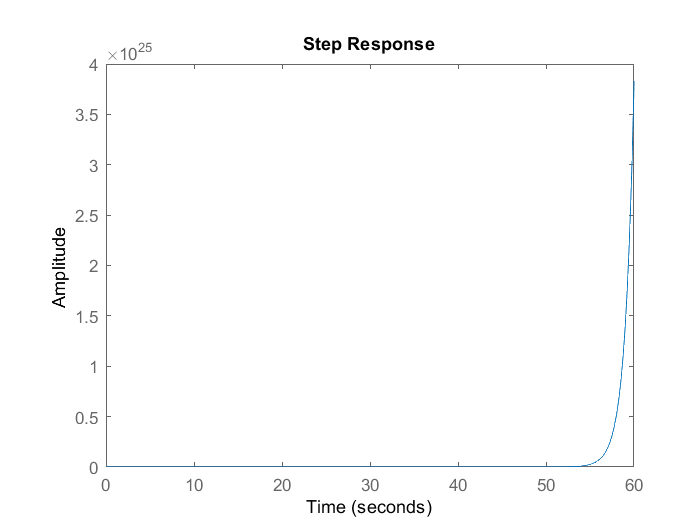

%%  Step response of Transfer function 1/((s-1)(s+2))
num1 = 1;
den1 = [1 1 -2];
g1 = tf(num1,den1);
figure(7)
step(g1);

stepinfo(g1)

ans = struct with fields:
        RiseTime: NaN
    SettlingTime: NaN
     SettlingMin: NaN
     SettlingMax: NaN
       Overshoot: NaN
      Undershoot: NaN
            Peak: Inf
        PeakTime: Inf


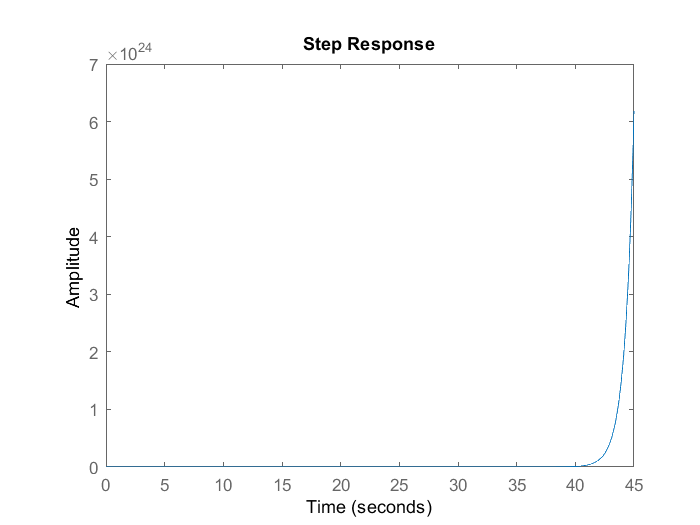


%% Step response of g1 with positive(1) feedback
m = feedback(g1,1,1);
figure(8)
step(m);

stepinfo(m)

ans = struct with fields:
        RiseTime: NaN
    SettlingTime: NaN
     SettlingMin: NaN
     SettlingMax: NaN
       Overshoot: NaN
      Undershoot: NaN
            Peak: Inf
        PeakTime: Inf


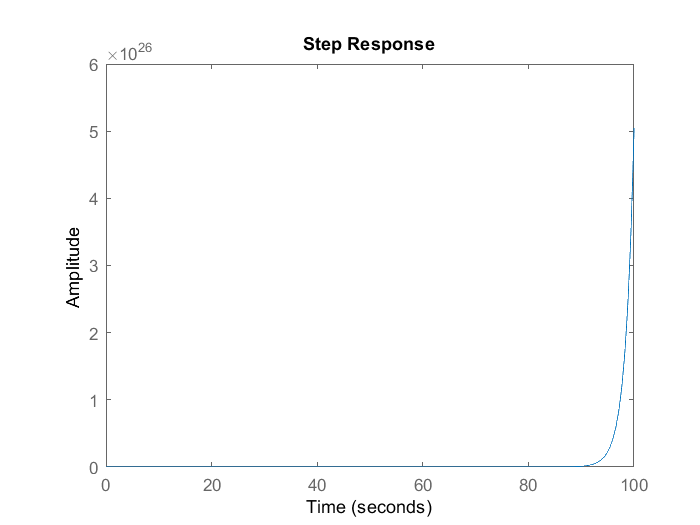

%% Step response of g1 with negative(1) feedback
m1 = feedback(g1,1);
figure(9)
step(m1);

stepinfo(m1)

ans = struct with fields:
        RiseTime: NaN
    SettlingTime: NaN
     SettlingMin: NaN
     SettlingMax: NaN
       Overshoot: NaN
      Undershoot: NaN
            Peak: Inf
        PeakTime: Inf


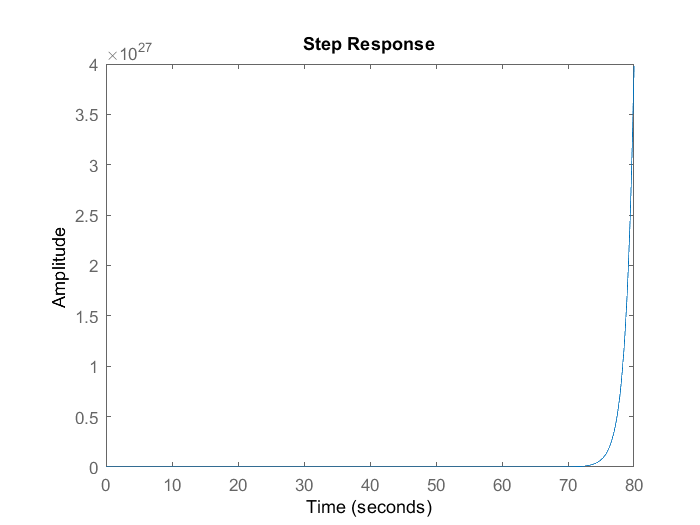

%% step response of g1 with s+1 pole in -ve feedback path
h1 = tf(1,[1 1]);
m2 = feedback(g1,h1);
figure(10)
step(m2);

stepinfo(m2)

ans = struct with fields:
        RiseTime: NaN
    SettlingTime: NaN
     SettlingMin: NaN
     SettlingMax: NaN
       Overshoot: NaN
      Undershoot: NaN
            Peak: Inf
        PeakTime: Inf


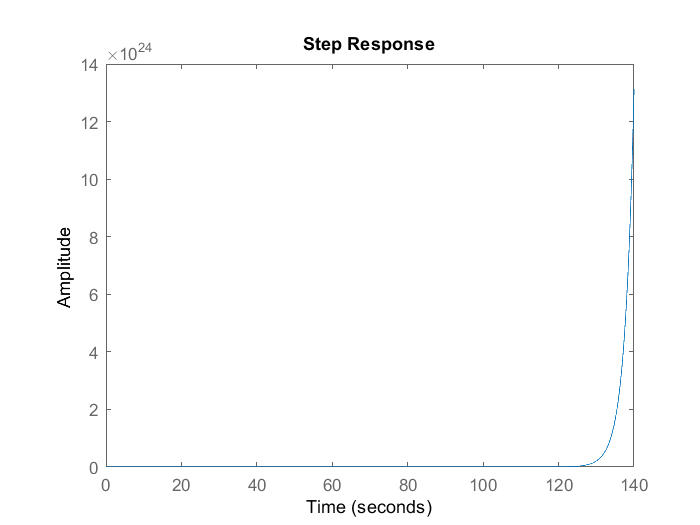

%% step response of g1 with s+1 zero in -ve feedback path
h2 = tf([1 1],1);
m3 = feedback(g1,h2);
figure(11)
step(m3);

stepinfo(m3)

ans = struct with fields:
        RiseTime: NaN
    SettlingTime: NaN
     SettlingMin: NaN
     SettlingMax: NaN
       Overshoot: NaN
      Undershoot: NaN
            Peak: Inf
        PeakTime: Inf


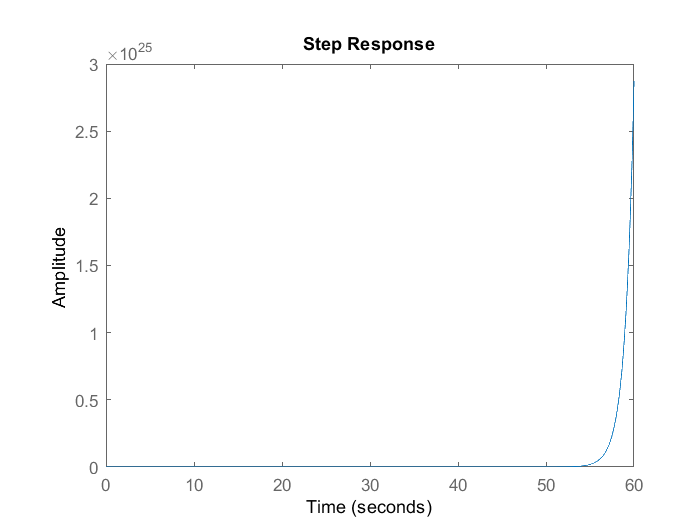

%% step response of g1 with s-1 zero in -ve feedback path
h3 = tf([1 -1],1);
m4 = feedback(g1,h3);
figure(12)
step(m4);

stepinfo(m4)

ans = struct with fields:
        RiseTime: NaN
    SettlingTime: NaN
     SettlingMin: NaN
     SettlingMax: NaN
       Overshoot: NaN
      Undershoot: NaN
            Peak: Inf
        PeakTime: Inf
